# 1.2.14.   Аппроксимация данных 

**Лекция**

## **Аппроксимация данных многочленом (полиномом)**

В MATLAB имеется возможность аппроксимировать данные многочленом с помощью специальной функции:

`    polyfit(``x,y,n``)`,

где `x` и` y` - данные, которые требуется аппроксимировать, а n - порядок аппроксимирующего многочлена. 

Для примера выполним кубическую аппроксимацию данных, полученных с помощью следующей функции:    


$$y(x)=0.3x^3-2x^2+x+8-\sinh(x/2)$$


x1 = 0:1:10;
y1 = 0.3*x1.^3 - 2*x1.^2 + x1 + 8 - sinh(x1./2) ;
p1 = polyfit(x1,y1,3) % Аппроксимация многочленом 3-го порядка, т. е. кубическая

p1 =     0.1128   -0.4302   -3.3484    9.3198


Результат функции polyfit является набор коэффициентов многочлена, начиная со старшего. В рассмотреном случае аппроксимирующий многочлен имеет вид:


$$p(x)=0.11x^3-0.43x^2-3.35x+9.3$$


Чтобы получить данные, соотвествующие многочлену с найдеными коэффициентами, следует воспользоваться функцией

    `polyval(``p,x``)``,`

где `p` - вектор с коэффициентами многочлена начиная со старшего, а `x` - вектор, каждый элемент которого будет подставлен в уравнение многочлена. 

Исходные данные и кривая аппроксимирующий многочлен показаны на графике ниже:

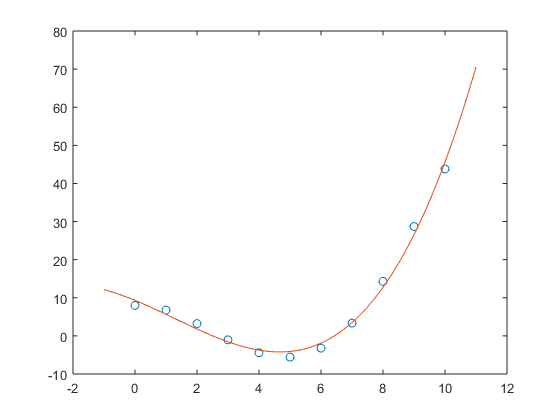

plot(x1,y1, ' o')
hold on
xf1 = -1:0.1:11;
yf1 = polyval(p1,xf1);
plot(xf1,yf1)
hold off

В случае, если абсолютные величины данных для аппроксимации большие, то в таком случае требуется центрирование и масштабирование. Функция `polyfit` сама может центрировать и масштабировать данные, выдавая как результат двхкомпонентный вектор, содержащий соответствующие коэффициенты. В том же формате, этот вектор может быть подан на функцию `polyval`. Пример:

[ps1,~,scl1] = polyfit(x1,y1,3);    
scl1        % Вектор центрирования и масштабирования
ys1 = polyval(ps1,xf1,[],scl1);
ys1 - yf1

ans = 	1.0e+-13 *

    0.1599    0.1599    0.1599    0.1954    0.1599    0.1776    0.1243    0.1421    0.1243    0.0888    0.1066    0.1421    0.1066    0.1066    0.1066    0.1155    0.0977    0.0711    0.0799    0.0711    0.0888    0.0533    0.0533    0.0444    0.0266    0.0178    0.0266    0.0266    0.0089    0.0178         0    0.0089   -0.0089   -0.0089   -0.0178   -0.0355   -0.0266   -0.0133   -0.0355   -0.0311   -0.0266   -0.0533   -0.0444   -0.0488   -0.0577   -0.0666   -0.0666   -0.0755   -0.0844   -0.0844


Больше информации об аппроксимации данных многочленами можно найти в соответствующих главах документации:

## **Аппроксимация данных функцией**

В случае, если данные требуется аппроксимировать не полиномом, а более сложной нелинейной функцией (гауссиан, экспонента и т. п.), используется функция `fit`. 

    `fit``(x,y,'Функция')`

Пример:

x2 = (0:0.1:2)';
y2 = 0.25*exp(2*x2) + randn(21,1);
plot(x2,y2,' o')
hold on
f2 = fit(x2,y2,'exp1')

f2 =      General model Exp1:
     f2(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.2071  (0.03874, 0.3754)
       b =       2.134  (1.689, 2.579)

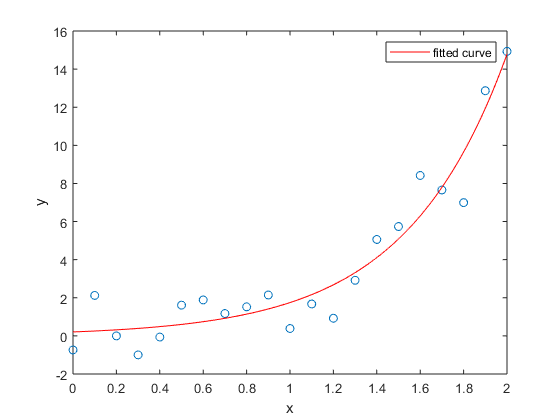

plot(f2)
hold off

Для аппроксимации можно использовать и другие встроенные в MATLAB функци:

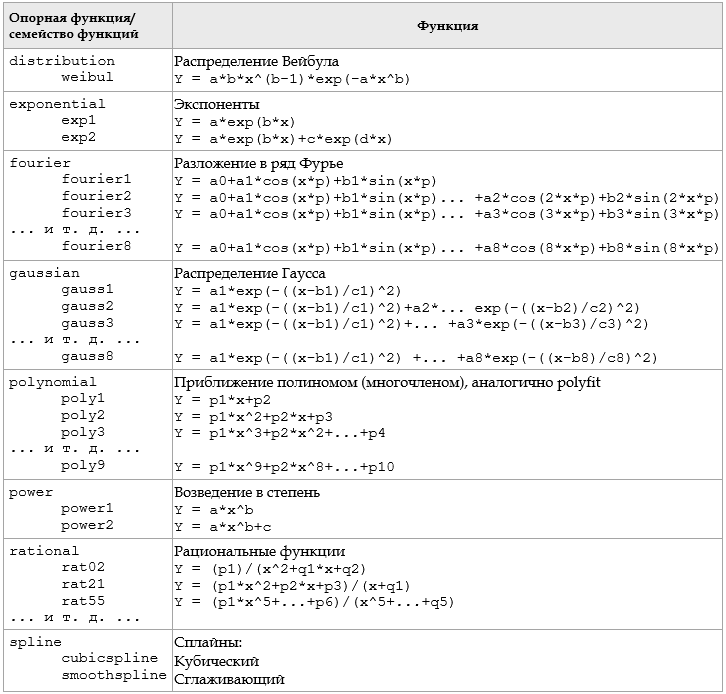

Также имеется возможность аппроксимировать данные пользовательскими функциями. Для того, чтобы использовать функцию, её сначало надо записать в виде массива символов:

y3 = (-1:0.2:1)';
x3 = - y3.^3+3;
y3 = y3+1.2;
plot(x3,y3, ' o')
FermiDirakEqn = 'c/(exp((x-a)/b)+1)';   % Пользовательская функция, распределение Ферми-Дирака
f3 = fit(x3,y3,FermiDirakEqn)

f3 =      General model:
     f3(x) = c/(exp((x-a)/b)+1)
     Coefficients (with 95% confidence bounds):
       a =       3.039  (2.944, 3.133)
       b =      0.1983  (0.08667, 0.3099)
       c =       2.209  (1.845, 2.573)

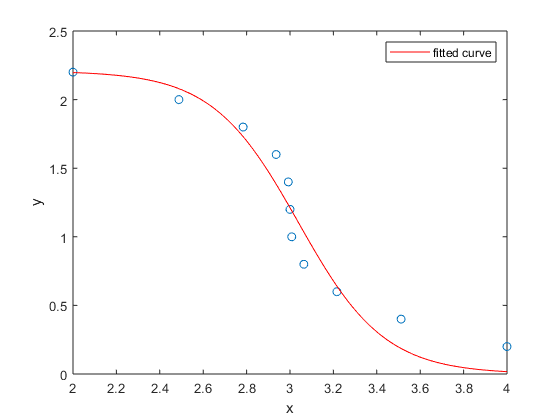

hold on
plot(f3)
hold off

Более подробно о функции `fit `и её возможностях можно прочитать в документации:

## **Интерполяция в MATLAB**

В MATLAB имеются возможности по интерполяции и экстраполяции для одномерных данных, в том числе и для комплексных (`interp1`), для двумерных данных (`interp2`) как, например, поверхности, для трехмерных данных (`interp3`) и для данных порядка n (`interpn`, количество данных задаётся параметром). 

Синтаксис и методы интерполяции у них похожие. Рассмотрим на примере `interp1`:

    `interp``(x, v, xq, МетодИнтерполяции)`,

где `x` и `v` вектора, причем $v = v(x)$, а вектор `xq` - координата, в которой значение требуется найти интерполяцией. По умолчанию, метод интерполяции - линейный:

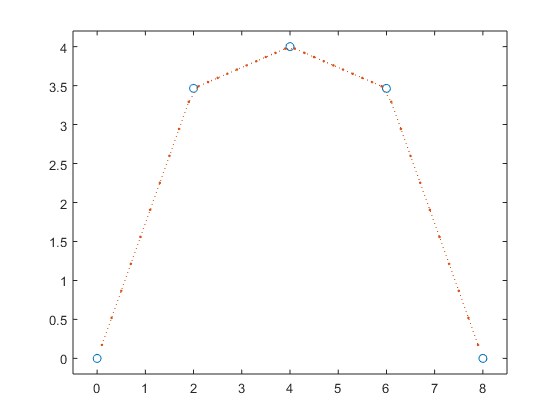

x4 = (0:2:8);
y4 =  (16 - (x4 - 4).^2).^(1/2);
xq4 = (0.1:0.2:7.9);
yq4 = interp1(x4,y4,xq4);       % Линейная интерполяция по умолчанию
plot(x4,y4, ' o')
hold on
plot(xq4,yq4,':.')
xlim([-0.5 8.5])
ylim([-0.2 4.2])
hold off

Другие встроенные методы интерполяции представлены в таблице:

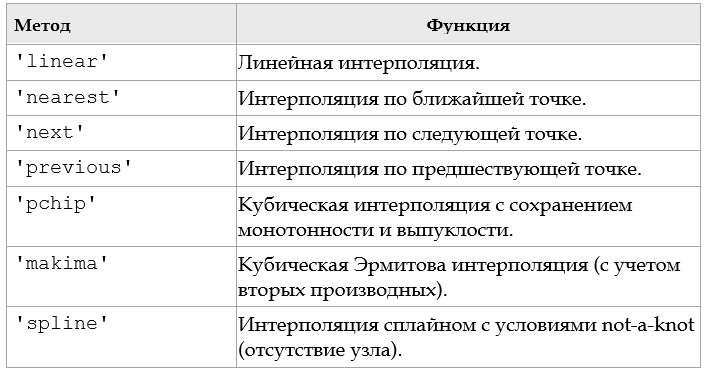

Пример кубической интерполяции в сравнении с линейной:

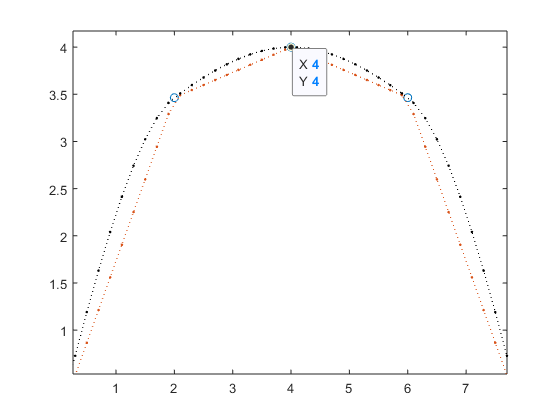

%xq4 = (0.1:0.2:7.9);
yq4_cub = interp1(x4,y4,xq4,'pchip');       % Линейная интерполяция по умолчанию
plot(x4,y4, ' o')
hold on
plot(xq4,yq4,':.')
plot(xq4,yq4_cub, ':.k')
xlim([-0.5 8.5])
ylim([-0.2 4.2])
hold off

Больше информации об интерполяции в MATLAB можно найти в документации:

## **Использование интерфейса Curve Fitting Tool**